clc
clear
reference_Input_Grader = 20;
stepRef = pi/180*reference_Input_Grader;
% Kp = 2.7;
% Ki = .018;
% Kd = 2.3;
Kp = 1;
Ki = 1;
Kd = 1;

simData = sim('PID_Sim');
ref = simData.yout{3}.Values.Data;
uout = simData.yout{2}.Values.Data;
yout = simData.yout{1}.Values.Data;
uoutSat = simData.yout{4}.Values.Data;
tout = simData.tout;
omega_max = (max(uout)/0.175)/0.011

omega_max = 1.8315e+04

omega_max_sat = (max(uoutSat)/0.175)/0.011

omega_max_sat = 1.0000e+03

figure()
S = stepinfo(yout, tout, stepRef)

S = struct with fields:
         RiseTime: 1.0565
    TransientTime: NaN
     SettlingTime: NaN
      SettlingMin: 0.0343
      SettlingMax: 0.6647
        Overshoot: 90.4306
       Undershoot: 0
             Peak: 0.6647
         PeakTime: 3.0316


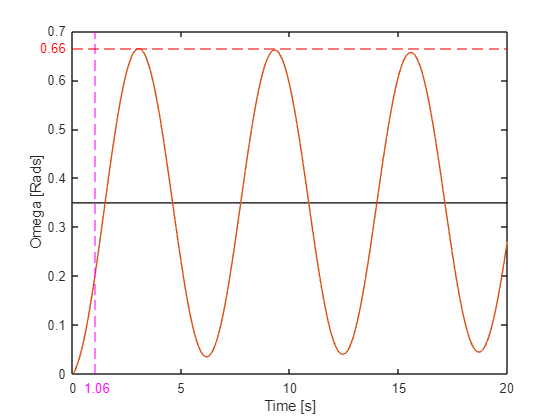

plot(tout,ref,'black',tout, yout)
xlabel('Time [s]');
ylabel('theta [Rad]');
xline(S.RiseTime,'--',Color='[1,0,1]')
xline(S.SettlingTime,'--',Color='[1,0,1]')
yline(S.Peak,'--',Color='[1,0,0]')
text(-1.5, S.Peak, sprintf('%.2f', S.Peak),Color='[1,0,0]');
text(S.RiseTime-0.55, -0.03, sprintf('%.2f', S.RiseTime),Color='[1,0,1]');
text(S.SettlingTime-0.55, -0.017, sprintf('%.2f', S.SettlingTime),Color='[1,0,1]');

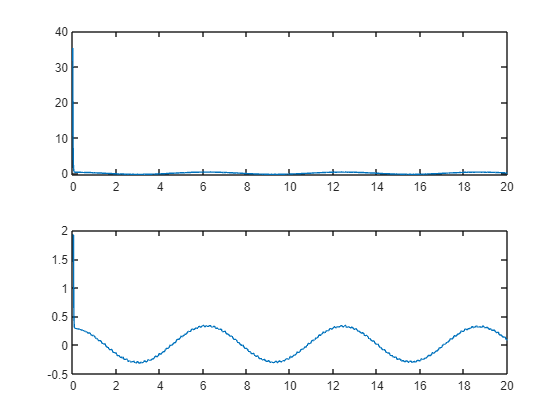


figure()
subplot(2,1,1)
plot(tout,uout)
subplot(2,1,2)
plot(tout,uoutSat)